%observations
obs = 1 + randn(1,10);


% priors
mu0 = 0;
lbd0 = 3;
a0 = 2;
b0 = 2;

N = length(obs);
y_m = mean(obs);
sigm_y2 = 1/N*sum((obs-y_m).^2);
lbd = lbd0 + N;
m = (lbd0*mu0 + N*y_m)/(N + lbd0);
a = a0 + N/2;
b = b0 + 0.5*(N*lbd0*(mu0-y_m)^2/(N + lbd0) + N*sigm_y2);

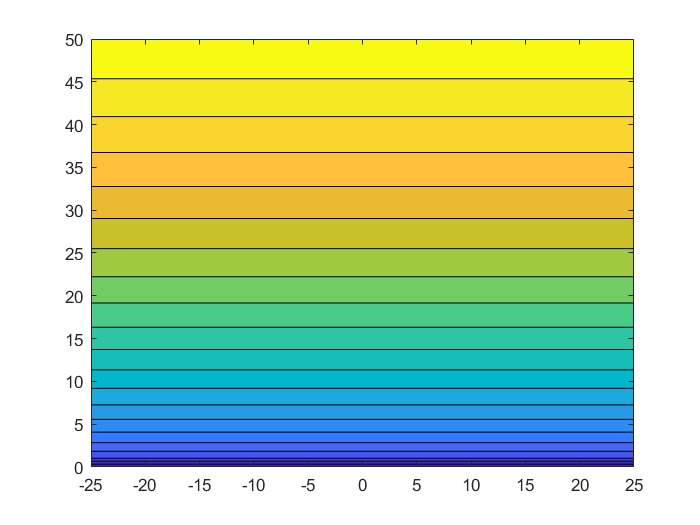

mu = linspace(-25,25,50);
taoo = linspace(0,50,50);
[MU,TAO] = meshgrid(mu,taoo);
POST = sqrt(lbd*TAO./(2*pi))*exp(-lbd*TAO./2*(MU-m).^2)*b^a*TAO.^(a-1)/gamma(a)*exp(-b*TAO);
contourf(MU,TAO,POST,20)